# Mohammadreza Arani

## Convex Optimization

## 810100511

% Project 6:

In this project, the problem is to maximize diversification in a portfolio so that we have maximum diversity in equity at a certain portfolio. ==> Meaning we have to choose maximum number of shares in a market!

The Diversity function here is defined and given as:

with some given constraints the problem becomes:

Maximum value of a share is equal to M.

Summation of shares shall be unique value.

We always seek for ultimate score so we want to get the full credit! ==>

we solve this problem with a convex optimization format not a quasiconvex which can be solved via bi-section method!

In solving this question a feature helps the most and it is given in the hint as:

"Note also that *D*(*tx*) = *D*(*x*) for any *t > *0.  "

So, the change of variable with this hint can be:


$$\begin{array}{l}
x=\frac{y}{\tau };\Rightarrow D\left(x\right)=D\left(\tau \;x\right)=D\left(y\right)\Rightarrow \\
\frac{\left(\sigma {\;}^T x\right)}{{\left(x^T \Sigma \;x\right)}^{\frac{1}{2}} }=\frac{\left(\sigma {\;}^T \frac{y}{\tau \;}\right)}{\frac{1}{\tau \;}{\left(y^T \Sigma \;y\right)}^{\frac{1}{2}} }\Rightarrow \mathrm{choose}\;y\;\mathrm{and}\;\tau \;\mathrm{so}\;\mathrm{that}\;\sigma {\;}^T y=1;\\
\mathrm{and}\;\mathrm{the}\;\mathrm{constraint}\;1^T x=1\;\mathrm{becomes}:\;\\
\sum_i y_i =\tau \Rightarrow \\
\mathrm{our}\;\mathrm{objective}\;\mathrm{will}\;\mathrm{look}\;\mathrm{like}:\\
\mathrm{maximize}\;\frac{1}{{\left(y^T \Sigma \;y\right)}^{\frac{1}{2}} }\;\;\;\mathrm{which}\;\mathrm{is}\;\mathrm{equivalent}\;\mathrm{to}:\\
\mathrm{maximize}\;\;\;\;\frac{1}{\left(y^T \Sigma \;y\;\right)}\;\;\mathrm{which}\;\mathrm{is}\;\mathrm{equivalent}\;\mathrm{to}:
\end{array}$$


$\mathrm{minimize}\;\;\left(y^T \Sigma \;y\right)$;

    S.t.

        
$$\begin{array}{l}
\sum_i y_i =\tau \;;\;\\
\tau \;>0\;;\\
0\le y\le \tau \;M;
\end{array}$$


% As we saw, this will be a Convex Optimization problem!
% It can be solved using CVX_MATLAB!
% So we get the full credit out of this project :) 

## Part (b)

% Load Data:
clear; clc; close all;
load('max_divers_data.mat'); % Given M(20*1)  ,  n =20; sigma(20*1) and Sigma(20*20)
n = double(n);
M = double(M);

% Solve:

cvx_begin
    variables y(n,1) Tau(1)
        minimize(quad_form(y,Sigma))
    % Constraints:
        subject to
        sum(y)    ==     Tau         ;
        Tau       >=      0          ;
        sigma'*y  ==      1          ;
        y         >=      0          ;
        y         <=      M          ;     
cvx_end

 
Calling SDPT3 4.0: 64 variables, 21 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 21
 dim. of socp   var  = 22,   num. of socp blk  =  1
 dim. of linear var  = 41
 dim. of free   var  =  1 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.9e+01|4.1e+01|6.7e+05| 5.860071e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.973|8.8e-07|1.5e+00|3.4e+04| 5.861406e+03 -2.569144e+02| 0:0:00| chol  1  1 
 2|1.000|0.970|5.6e-07|2.8e-01|6.4e+03| 2.471626e+03 -1.603800e+02| 0:0:00

## Problem is SOlved!

disp("Optimal Value of Tau: "+num2str(Tau));

Optimal Value of Tau: 0.28542


disp("Optimal Values of y :");

Optimal Values of y :


disp(y'/Tau);

  Columns 1 through 11

    0.0260    0.0000    0.0235    0.0219    0.0000    0.0838    0.0445    0.0196    0.0176    0.2296    0.1075

  Columns 12 through 20

    0.0129    0.1483    0.0550    0.0105    0.0338    0.0990    0.0082    0.0334    0.0247



Optimal_cvx_y = cvx_optval;
disp(cvx_optval);

    0.0267



% Long-only portfolio:
cvx_begin
    variables x_long(n,1)
        minimize(quad_form(x_long,Sigma))
    % Constraints:
        subject to
        sum(x_long)    ==      1          ;
        x_long         >=      0          ;
        x_long         <=      M          ;   
cvx_end

 
Calling SDPT3 4.0: 63 variables, 21 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 21
 dim. of socp   var  = 22,   num. of socp blk  =  1
 dim. of linear var  = 40
 dim. of free   var  =  1 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.5e-01|2.1e+01|5.8e+05| 5.788165e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|3.4e-07|5.0e-01|1.8e+04| 5.396913e+03 -2.156547e+02| 0:0:00| chol  1  1 
 2|1.000|1.000|1.3e-07|2.5e-01|1.7e+03| 6.021244e+02 -1.086685e+02| 0:0:00

long_only_cvx_opt_val  = cvx_optval;
long_only_x = x_long;
disp("Optimal Value: "+num2str(cvx_optval))

Optimal Value: 0.1318



disp(long_only_x')

  Columns 1 through 11

    0.0219    0.0000    0.0042    0.0035    0.1053    0.0122    0.0137    0.0129    0.1671    0.1535    0.0412

  Columns 12 through 20

    0.0039    0.2000    0.0201    0.0000    0.2000    0.0180    0.0000    0.0069    0.0155



% we can see that Optimal Value of heuristic method is:
disp(Optimal_cvx_y/cvx_optval*100)

   20.2812



%percentage meaning we were 5 times better using Convex Optimization!

## Figures

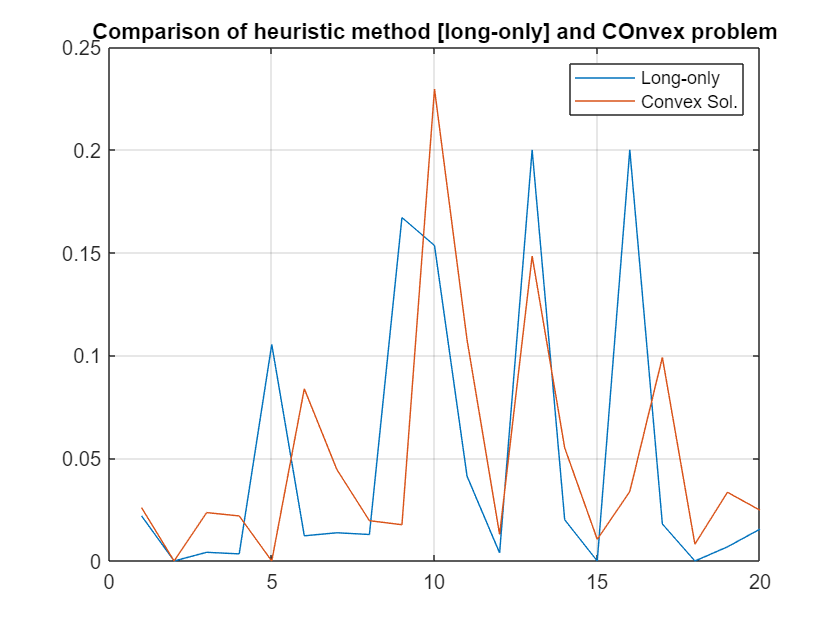

Fig1 = figure();
plot(x_long);
hold on
plot(y/Tau);
grid on
legend('Long-only','Convex Sol.');
title('Comparison of heuristic method [long-only] and COnvex problem');

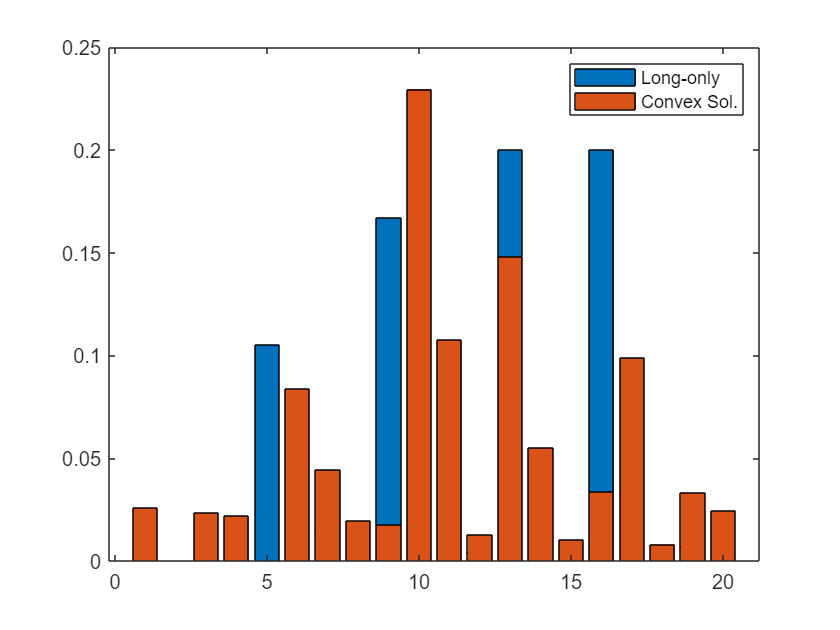

% Using Bar plot:
Fig2 = figure();
bar(x_long);
hold on
bar(y/Tau);
legend('Long-only','Convex Sol.');

% we can see that the orange color which represents Convex solution of the
% problem is more Diverse than Long-only solution!
% Please Note that both Solutions satisfies the given conditions!

